clc;
clear;
close all;

%% USER INPUT
website = 'google.com';   % Change to any website
num_pings = 10;           % Number of ping attempts

%% RUN PING COMMAND
% Windows command
cmd = sprintf('ping %s -n %d', website, num_pings);

[status, result] = system(cmd);

if status ~= 0
    error('Ping failed. Check internet or website.');
end

disp(result);


Pinging google.com [142.250.67.46] with 32 bytes of data:
Reply from 142.250.67.46: bytes=32 time=60ms TTL=112
Reply from 142.250.67.46: bytes=32 time=74ms TTL=112
Reply from 142.250.67.46: bytes=32 time=59ms TTL=112
Reply from 142.250.67.46: bytes=32 time=59ms TTL=112
Reply from 142.250.67.46: bytes=32 time=59ms TTL=112
Reply from 142.250.67.46: bytes=32 time=60ms TTL=112
Reply from 142.250.67.46: bytes=32 time=60ms TTL=112
Reply from 142.250.67.46: bytes=32 time=59ms TTL=112
Reply from 142.250.67.46: bytes=32 time=59ms TTL=112
Reply from 142.250.67.46: bytes=32 time=59ms TTL=112

Ping statistics for 142.250.67.46:
    Packets: Sent = 10, Received = 10, Lost = 0 (0% loss),
Approximate round trip times in milli-seconds:
    Minimum = 59ms, Maximum = 74ms, Average = 60ms




%% EXTRACT DELAY (RTT)

% Extract time=XXms values
tokens = regexp(result, 'time[=<]\s*(\d+)\s*ms', 'tokens');

rtt = [];

for i = 1:length(tokens)
    rtt = [rtt str2double(tokens{i}{1})];
end

%% PACKET LOSS EXTRACTION

loss_token = regexp(result, '(\d+)%\s*loss', 'tokens');

if ~isempty(loss_token)
    packet_loss = str2double(loss_token{1}{1});
else
    packet_loss = NaN;
end

%% RESULTS

fprintf('\n--- Analysis Results ---\n');


--- Analysis Results ---


fprintf('Website: %s\n', website);

Website: google.com


fprintf('Packets Sent: %d\n', num_pings);

Packets Sent: 10


fprintf('Packets Received: %d\n', length(rtt));

Packets Received: 10


fprintf('Packet Loss: %.2f %%\n', packet_loss);

Packet Loss: 0.00 %



if ~isempty(rtt)
    fprintf('Average Delay: %.2f ms\n', mean(rtt));
    fprintf('Minimum Delay: %.2f ms\n', min(rtt));
    fprintf('Maximum Delay: %.2f ms\n', max(rtt));
end

Average Delay: 60.80 ms


Minimum Delay: 59.00 ms


Maximum Delay: 74.00 ms


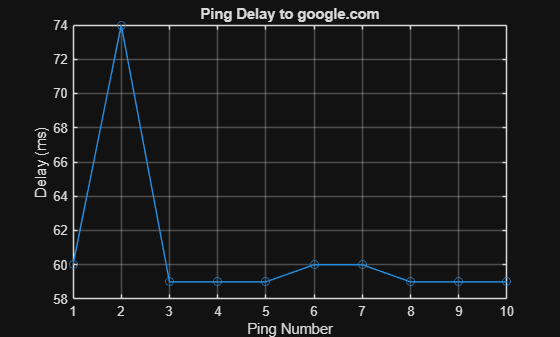


%% PLOT DELAY

if ~isempty(rtt)
    figure;
    plot(rtt, '-o');
    grid on;
    title(['Ping Delay to ', website]);
    xlabel('Ping Number');
    ylabel('Delay (ms)');
end